%1
T = import_airborne_gravity_data('Data/Q1/RESOURCES/NGS_GRAVD_Block_CN03_BETA1/NGS_GRAVD_Block_CN03_Gravity_Data_BETA1.txt')

T = 	1.0e+05 *

    0.0004   -0.0010    9.7849    0.0636
    0.0004   -0.0010    9.7849    0.0636
    0.0004   -0.0010    9.7849    0.0636
    0.0004   -0.0010    9.7849    0.0637
    0.0004   -0.0010    9.7849    0.0637
    0.0004   -0.0010    9.7849    0.0637
    0.0004   -0.0010    9.7849    0.0637
    0.0004   -0.0010    9.7849    0.0637
    0.0004   -0.0010    9.7849    0.0637
    0.0004   -0.0010    9.7849    0.0637


latitude = T(:,1);
longitude = T(:,2);
elipsoidal_height = T(:,4);
gravity_filtered = T(:,3);
Ellipsoid = make_Ellipsoid('WGS84')

Ellipsoid = struct with fields:
              GM: 3.9860e+14
           omega: 7.2921e-05
    gammaEquator: 9.7803e+05
       gammaPole: 9.8322e+05
               a: 6378137
               b: 6.3568e+06
               e: 0.0818
              e2: 0.0067
               f: 0.0034


%2 
%N_ggm = open('/Users/sunilbhavsar/Documents/CE678_PROJECT/Q2/RESOURCES/AIUB-CHAMP01S_a50de3dfc2ab0cdb9a2ae28b113f3398304202075281a813ba9cc27562a667af.gdf')
%a = open('/Users/sunilbhavsar/Documents/CE678_PROJECT/AIUB-CHAMP01S_a50de3dfc2ab0cdb9a2ae28b113f3398304202075281a813ba9cc27562a667af.gdf')
nggm = import_geoid_heights('Data/Q2/Downloaded_Data/GGM02C.gdf',latitude,longitude)

nggm =   -25.4579
  -25.4563
  -25.4547
  -25.4532
  -25.4516
  -25.4501
  -25.4485
  -25.4470
  -25.4455
  -25.4440


help calc_orthometric_height

 calc_orthometric_height(ellipsoidal_height,n_ggm) - calculates orthometric height
 
     INPUT
     1. Ellipsoidal height(meters)(double)
     2. nggm(meters)(double) - Geoid height from nggm model.   
     IMP- ellipsoidal_height and n_ggm should be mapped over same latitude and longitudes
     TIP- import ellipsoidal_height and n_ggm using  import_airborne_gravity_data and import_geoid_heights  
     to ensure same latitudes and longitudes for both vectors
  Long description



%adding 
orthometric_height = calc_orthometric_height(elipsoidal_height,nggm)

orthometric_height = 	1.0e+03 *

    6.3388
    6.3391
    6.3395
    6.3399
    6.3404
    6.3408
    6.3412
    6.3413
    6.3414
    6.3413


help remove_g_ggm

  remove_g_ggm(g_faa,g_ggm) calculates ong- wavelength gravity anomaly ( ∆gGGM) 
  by removing the effect of a global gravity field model from free air anomily values
  Inputs:
  g_faa   (double) - corresponding free air anomalies (mGals) 
  g_ggm   (double) - corresponding global gravity (mGals) 
  
 
  Output:
  g_msw   (double) - reduced gravity anomaly ∆gs&mw contains only the medium and the short wave- lengths.
  mapped over latitude and longitude of both g_ggm and f_faa
  IMP - Ensure that  g_faa and g_ggm are both imorted and calculated over same latitude and longitude vector
  TIP1 - Use  calc_free_air_anomaly for calculating g_faa
  TIP2 - Use  import_grav_anomaly for importing g_ggm



%3
Ellipsoid = make_Ellipsoid('WGS84');
free_air_anomily = gravity_filtered + calc_FAC(latitude,Ellipsoid,orthometric_height)-calc_gnorm_ellip_surface(latitude,Ellipsoid)

free_air_anomily = 	1.0e+03 *

   -3.8995
   -3.8996
   -3.8997
   -3.8999
   -3.9001
   -3.9003
   -3.9004
   -3.9005
   -3.9005
   -3.9005


faa = calc_free_air_anomaly(gravity_filtered,latitude,Ellipsoid,orthometric_height)

faa = 	1.0e+03 *

   -3.8995
   -3.8996
   -3.8997
   -3.8999
   -3.9001
   -3.9003
   -3.9004
   -3.9005
   -3.9005
   -3.9005


%4 hel

del_g_ggm = import_grav_anomaly('Data/Q4/GGM02C_Anomily.gdf',latitude,longitude)
del_g_s_and_mw = remove_g_ggm(free_air_anomily,del_g_ggm);

%5
g_atm_and_s_mw = remove_g_atm(del_g_s_and_mw,orthometric_height)

g_atm_and_s_mw = 	1.0e+03 *

   -3.9157
   -3.9158
   -3.9160
   -3.9162
   -3.9163
   -3.9165
   -3.9166
   -3.9167
   -3.9167
   -3.9168


%6

[Latitude_grid,Longitude_grid] = create_grid(latitude,longitude,0.01);


%7
files = ["Data/Q7/srtm_16_04/srtm_16_04.asc" "Data/Q7/srtm_17_04/srtm_17_04.asc"]

files = 1×2 string array
    "Data/Q7/srtm_16_04/srtm_16_04.asc"    "Data/Q7/srtm_17_04/srtm_17_04.asc"



files(1)

ans = "Data/Q7/srtm_16_04/srtm_16_04.asc"

H = combine_DEM_data(files,Latitude_grid,Longitude_grid)

H = 	1.0e+03 *

    0.7570    0.7670    0.7690    0.7690    0.7580    0.7680    0.7750    0.7750    0.7830    0.7730    0.7790    0.7830    0.7800    0.7740    0.7870    0.7780    0.7720    0.7870    0.7850    0.7790    0.7700    0.7670    0.7790    0.7820    0.7840    0.7900    0.7980    0.8060    0.8080    0.8080    0.8110    0.8050    0.8110    0.8180    0.8210    0.8150    0.8220    0.8210    0.8200    0.8210    0.8180    0.8170    0.8240    0.8360    0.8430    0.8440    0.8500    0.8380    0.8460    0.8500
    0.7660    0.7710    0.7750    0.7670    0.7550    0.7720    0.7750    0.7780    0.7790    0.7830    0.7830    0.7890    0.7900    0.7870    0.7970    0.7830    0.7830    0.7870    0.7930    0.7860    0.7810    0.7720    0.7780    0.7840    0.7940    0.7980    0.7980    0.8040    0.8060    0.8030    0.8080    0.7970    0.8070    0.8170    0.8090    0.8150    0.8280    0.8140    0.8190    0.8020    0.8220    0.8260    0.8400    0.8510    0.8280    0.8450    0.8410    0.8290   

tc = terrain_correction_fft(H,lat,long,0.01);

Padding array
Determining spatial grids
Setting up integration kernel


l3 = 	1.0e+18 *

    1.0309    1.0287    1.0264    1.0242    1.0220    1.0198    1.0176    1.0153    1.0131    1.0109    1.0087    1.0065    1.0044    1.0022    1.0000    0.9978    0.9956    0.9935    0.9913    0.9891    0.9870    0.9848    0.9826    0.9805    0.9783    0.9762    0.9741    0.9719    0.9698    0.9677    0.9655    0.9634    0.9613    0.9592    0.9571    0.9550    0.9529    0.9508    0.9487    0.9466    0.9445    0.9424    0.9403    0.9382    0.9362    0.9341    0.9320    0.9300    0.9279    0.9258
    1.0292    1.0270    1.0248    1.0226    1.0203    1.0181    1.0159    1.0137    1.0115    1.0093    1.0071    1.0049    1.0027    1.0005    0.9984    0.9962    0.9940    0.9918    0.9897    0.9875    0.9853    0.9832    0.9810    0.9789    0.9767    0.9746    0.9724    0.9703    0.9682    0.9661    0.9639    0.9618    0.9597    0.9576    0.9555    0.9534    0.9513    0.9492    0.9471    0.9450    0.9429    0.9408    0.9387    0.9366    0.9346    0.9325    0.9304    0.9284  

FFT kernel for TC
FFT H^2
FFT H
FFT ones
Computing TC


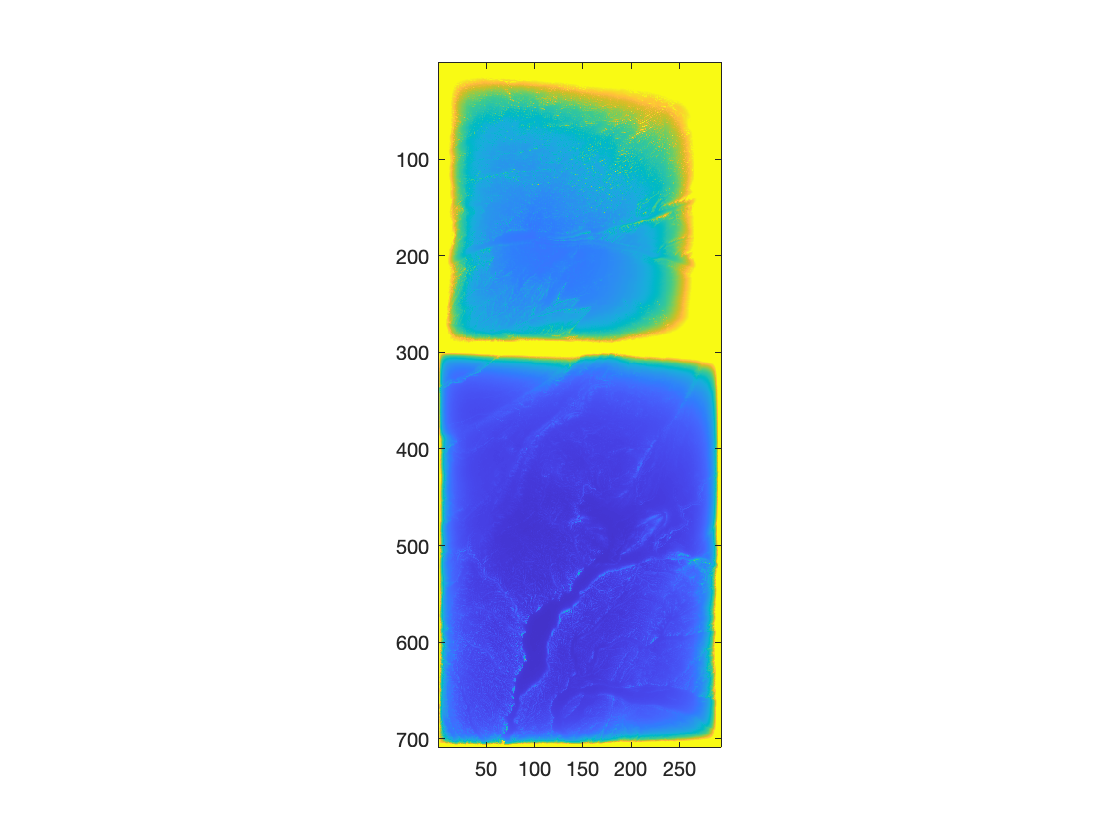


imagesc(tc)
axis image
caxis([0 1])

gfaye = calc_gfaye(g_atm_and_s_mw,longitude,latitude,tc,Latitude_grid,Longitude_grid);

%8
%and 9
help calc_gfaye

 calc_gfaye(g_atm_and_s_mw,g_atm_and_s_mw_longitudes,g_atm_and_s_mw_latitudes,tc,Latitude_grid,Longitude_grid)
  calculates faye anomily by removing terrain correction from g_atm_and_s_mw.
  INPUT -
  1. g_atm_and_s_mw (double)- medium and short wave anomaly(mGals)
  2. g_atm_and_s_mw_longitudes(double) - Latitude(degrees) vector on which g_atm_and_s_mw is mapped
  3. g_atm_and_s_mw_latitudes(double) - Latitude(degrees) vector on which g_atm_and_s_mw is mapped
  4. tc (mGals) - Terrain correction calculated using terrain_correction
  5. Latitude_grid(double) - Latitude(degrees) matrix used for tc 
  6. Longitude_grid(double) - Longitude(degrees) matrix used for tc 
  OUTPUT - 
  gfaye(mGals) over Latitude and Longitude grid
  TIP- 
  Use create_grid for forming Latitude and Longitude grids.



help import_grav_anomaly

  import_grav_anomaly(filePath,Latitudes,Longitudes) imports gravity anomilies
  from the GGM model into the latitude and longitude vectors specified.
  INPUTS:
    1- filePath - path of the file (.gdf format) downloaded from here with minimum resolution 0.01 and 
                  mapping our area of interest
    2 Latitude(double) -  (degrees)The Latitude vector of area of interest in increasing order.
    3 longitude(double) - (degrees)The longitude vector of area of interest in increasing order.
    OUTPUT
     gravity anomily(double) - gravity anomily(in mGals) vector of ggm model over the given Latitude and longitude vector 
 TIP - Use the vectors obtained from importing gravity airborne data 
  Help for importing airborne data



Tr = calc_disturb_potential(H,Latitude_grid,Longitude_grid,gfaye);

max_lat = 43.0108

min_lat = 40.0908

max_lon = -95.8837

min_lon = -102.9637

lat_center = 41.5508

lon_center = -99.4237

si =     3.0506    3.0456    3.0407    3.0358    3.0309    3.0261    3.0213    3.0165    3.0117    3.0069    3.0022    2.9975    2.9929    2.9882    2.9836    2.9790    2.9744    2.9699    2.9654    2.9609    2.9565    2.9520    2.9476    2.9433    2.9389    2.9346    2.9303    2.9260    2.9218    2.9176    2.9134    2.9093    2.9051    2.9010    2.8970    2.8929    2.8889    2.8850    2.8810    2.8771    2.8732    2.8693    2.8655    2.8617    2.8579    2.8542    2.8505    2.8468    2.8432    2.8395
    3.0439    3.0390    3.0340    3.0291    3.0243    3.0194    3.0146    3.0098    3.0050    3.0002    2.9955    2.9908    2.9861    2.9815    2.9768    2.9722    2.9677    2.9631    2.9586    2.9541    2.9496    2.9452    2.9408    2.9364    2.9320    2.9277    2.9234    2.9191    2.9149    2.9107    2.9065    2.9023    2.8982    2.8941    2.8900    2.8860    2.8820    2.8780    2.8740    2.8701    2.8662    2.8623    2.8585    2.8547    2.8509    2.8471    2.8434    2.8397    2.8361    

Tr_stokes_fft = 	1.0e+07 *

   2.0168 + 0.0000i   1.7680 + 0.0102i   1.1613 + 0.0130i   0.5189 + 0.0080i   0.1287 + 0.0021i   0.0702 + 0.0023i   0.2049 + 0.0092i   0.3189 + 0.0160i   0.2910 + 0.0162i   0.1579 + 0.0095i   0.0432 + 0.0027i   0.0329 + 0.0027i   0.1065 + 0.0095i   0.1734 + 0.0163i   0.1647 + 0.0163i   0.0921 + 0.0095i   0.0256 + 0.0027i   0.0214 + 0.0027i   0.0716 + 0.0095i   0.1185 + 0.0163i   0.1143 + 0.0163i   0.0647 + 0.0095i   0.0181 + 0.0027i   0.0158 + 0.0027i   0.0536 + 0.0095i   0.0896 + 0.0163i   0.0871 + 0.0163i   0.0496 + 0.0095i   0.0138 + 0.0027i   0.0124 + 0.0027i   0.0427 + 0.0094i   0.0716 + 0.0162i   0.0700 + 0.0162i   0.0400 + 0.0094i   0.0111 + 0.0027i   0.0101 + 0.0027i   0.0352 + 0.0094i   0.0594 + 0.0161i   0.0582 + 0.0161i   0.0333 + 0.0094i   0.0092 + 0.0026i   0.0085 + 0.0026i   0.0298 + 0.0093i   0.0505 + 0.0161i   0.0496 + 0.0161i   0.0284 + 0.0093i   0.0078 + 0.0026i   0.0073 + 0.0026i   0.0257 + 0.0093i   0.0436 + 0.0160i
   1.8218 + 0.0054i  

Nr = calc_undulation(Tr,Latitude_grid,Ellipsoid);


%10
N_co_geoid = calc_n_cogeoid(Nr,nggm,latitude,longitude,Latitude_grid,Longitude_grid);



%11
 R = Ellipsoid.a

R = 6378137

 G = 6.67*10^-6

G = 6.6700e-06

 rho = 2670

rho = 2670

 gamma = calc_gnorm_ellip_surface(Latitude_grid,Ellipsoid);
 Xm=Longitude_grid*111319.9*cosd(mean(mean(Latitude_grid)));
 Ym=Latitude_grid*111319.9;
 
 rq = sqrt((Xm-mean(mean(Xm))).^2+(Ym-mean(mean(Ym))).^2)

rq = 	1.0e+05 *

    3.3673    3.3620    3.3566    3.3513    3.3460    3.3408    3.3356    3.3304    3.3252    3.3201    3.3150    3.3099    3.3049    3.2999    3.2949    3.2900    3.2850    3.2802    3.2753    3.2705    3.2657    3.2609    3.2562    3.2515    3.2468    3.2422    3.2376    3.2330    3.2284    3.2239    3.2194    3.2150    3.2106    3.2062    3.2018    3.1975    3.1932    3.1890    3.1848    3.1806    3.1764    3.1723    3.1682    3.1642    3.1602    3.1562    3.1522    3.1483    3.1444    3.1406
    3.3600    3.3546    3.3493    3.3440    3.3387    3.3334    3.3282    3.3230    3.3179    3.3127    3.3076    3.3025    3.2975    3.2925    3.2875    3.2825    3.2776    3.2727    3.2678    3.2630    3.2582    3.2534    3.2486    3.2439    3.2392    3.2346    3.2300    3.2254    3.2208    3.2163    3.2118    3.2073    3.2029    3.1985    3.1942    3.1898    3.1855    3.1813    3.1770    3.1729    3.1687    3.1646    3.1605    3.1564    3.1524    3.1484    3.1444    3.1405  

 rq3 =rq.^3 

rq3 = 	1.0e+16 *

    3.8181    3.7999    3.7819    3.7640    3.7462    3.7287    3.7112    3.6939    3.6768    3.6598    3.6430    3.6263    3.6098    3.5934    3.5771    3.5610    3.5451    3.5293    3.5136    3.4981    3.4827    3.4675    3.4524    3.4375    3.4227    3.4080    3.3935    3.3791    3.3649    3.3508    3.3369    3.3231    3.3094    3.2958    3.2824    3.2692    3.2560    3.2431    3.2302    3.2175    3.2049    3.1924    3.1801    3.1679    3.1559    3.1440    3.1322    3.1205    3.1090    3.0976
    3.7934    3.7752    3.7572    3.7393    3.7216    3.7041    3.6867    3.6694    3.6523    3.6354    3.6186    3.6020    3.5855    3.5691    3.5529    3.5368    3.5209    3.5052    3.4895    3.4741    3.4587    3.4435    3.4285    3.4136    3.3988    3.3842    3.3697    3.3554    3.3412    3.3271    3.3132    3.2994    3.2858    3.2723    3.2589    3.2457    3.2326    3.2196    3.2068    3.1941    3.1815    3.1691    3.1568    3.1447    3.1327    3.1208    3.1090    3.0974 

 res = 0.01;
 Delta=111319.9*res;
 % kernel weighting 
 W=(rq3./(2*Delta)).*(((rq+Delta/2).^2-(rq-Delta/2).^2)./(((rq+Delta/2).^2).*((rq-Delta/2).^2)));
 K=W./rq3;
% apply a spherical cap to zero the kernel off outside some set radius


% Free up some memory

%% compute 2D fft for the Heights, Heights^2 and kernel

 disp('FFT kernel for TC')

FFT kernel for TC


 rq(rq<111391.1*0.01) = 0;
 FK=fft2(fftshift(K));
 deltaN_indirect_term1 = pi*H.^2

deltaN_indirect_term1 = 	1.0e+06 *

    1.8003    1.8482    1.8578    1.8578    1.8050    1.8530    1.8869    1.8869    1.9261    1.8772    1.9064    1.9261    1.9113    1.8821    1.9458    1.9016    1.8723    1.9458    1.9359    1.9064    1.8627    1.8482    1.9064    1.9212    1.9310    1.9607    2.0006    2.0409    2.0510    2.0510    2.0663    2.0358    2.0663    2.1021    2.1176    2.0867    2.1227    2.1176    2.1124    2.1176    2.1021    2.0970    2.1331    2.1956    2.2326    2.2379    2.2698    2.2062    2.2485    2.2698
    1.8433    1.8675    1.8869    1.8482    1.7908    1.8723    1.8869    1.9016    1.9064    1.9261    1.9261    1.9557    1.9607    1.9458    1.9956    1.9261    1.9261    1.9458    1.9756    1.9409    1.9162    1.8723    1.9016    1.9310    1.9806    2.0006    2.0006    2.0308    2.0409    2.0257    2.0510    1.9956    2.0460    2.0970    2.0561    2.0867    2.1538    2.0816    2.1073    2.0207    2.1227    2.1434    2.2167    2.2751    2.1538    2.2432   


 deltaN_indirect_term2 = ifft2(fft2(H.^3).*FK)

deltaN_indirect_term2 =     9.1338    8.9189    8.7089    8.5498    8.6219    8.8191    8.8295    8.9619    8.9325    9.0516    9.1141    9.1192    9.0748    9.2163    9.2008    9.1321    9.3914    9.2718    9.1559    8.9812    8.8826    8.9936    9.1028    9.2792    9.4287    9.5853    9.7020    9.7502    9.7446    9.8092    9.7678    9.9015    9.9953   10.1690   10.1240   10.0978   10.0312   10.1329   10.3662   10.4939   10.6739   10.6284   10.7067   11.0570   11.0504   11.0404   11.0375   11.1962   11.2542   11.4076
    9.4884    9.2373    9.0260    8.8243    9.0278    9.0805    9.1865    9.2726    9.3003    9.4106    9.5785    9.6184    9.5693    9.7321    9.5981    9.5751    9.6612    9.7030    9.5494    9.4878    9.3898    9.4271    9.4562    9.5457    9.7154    9.7989    9.9153    9.8516   10.0054   10.0833   10.0348   10.2071   10.2753   10.2688   10.3813   10.4857   10.5329   10.5927   10.5790   10.9241   11.0394   11.1480   11.4988   11.2754   11.2703   11.3348   11.2164   11

 deltaN_indirect_term3 = - H.^3.*ifft2(fft2(1).*FK)

deltaN_indirect_term3 =    -0.2289   -0.0376   -0.0118   -0.0050   -0.0025   -0.0015   -0.0010   -0.0007   -0.0005   -0.0003   -0.0003   -0.0002   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0656   -0.0231   -0.0094   -0.0043   -0.0022   -0.0014   -0.0009   -0.0006   -0.0005   -0.0003   -0.0003   -0.0002   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0

 W=(rq.^5./(2*Delta)).*(((rq+Delta/2).^2-(rq-Delta/2).^2)./(((rq+Delta/2).^2).*((rq-Delta/2).^2)));
 K = W./(rq.^5);
 FK5 = fft2(fftshift(K))
 deltaN_indirect_term4 =  + 3*R^2/40 .*ifft2(fft2(H.^5).*FK)

deltaN_indirect_term4 = 	1.0e+20 *

    0.1759    0.1678    0.1608    0.1557    0.1576    0.1633    0.1634    0.1674    0.1664    0.1700    0.1719    0.1720    0.1707    0.1751    0.1746    0.1725    0.1808    0.1769    0.1732    0.1677    0.1645    0.1678    0.1711    0.1766    0.1814    0.1864    0.1903    0.1919    0.1918    0.1938    0.1924    0.1968    0.1999    0.2057    0.2041    0.2033    0.2012    0.2044    0.2123    0.2169    0.2233    0.2216    0.2244    0.2368    0.2366    0.2364    0.2362    0.2419    0.2439    0.2494
    0.1841    0.1746    0.1674    0.1609    0.1667    0.1680    0.1710    0.1735    0.1743    0.1776    0.1828    0.1840    0.1824    0.1876    0.1833    0.1825    0.1852    0.1865    0.1816    0.1796    0.1766    0.1776    0.1785    0.1813    0.1866    0.1893    0.1931    0.1911    0.1960    0.1985    0.1969    0.2025    0.2048    0.2045    0.2082    0.2118    0.2133    0.2153    0.2150    0.2267    0.2307    0.2346    0.2471    0.2391    0.2389    0.2411   

 deltaN_indirect_term5 = - H.^5.*conv2(1,rq.^5,'same')

deltaN_indirect_term5 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0 

 deltaN_indirect = -(G*rho./gamma).*(deltaN_indirect_term1+deltaN_indirect_term2 +deltaN_indirect_term3+deltaN_indirect_term4+deltaN_indirect_term5)

deltaN_indirect = 	1.0e+12 *

   -0.3196   -0.3048   -0.2922   -0.2829   -0.2864   -0.2967   -0.2970   -0.3041   -0.3023   -0.3088   -0.3123   -0.3126   -0.3101   -0.3181   -0.3173   -0.3135   -0.3284   -0.3214   -0.3147   -0.3047   -0.2989   -0.3048   -0.3109   -0.3209   -0.3295   -0.3387   -0.3458   -0.3487   -0.3484   -0.3522   -0.3495   -0.3575   -0.3632   -0.3737   -0.3708   -0.3693   -0.3655   -0.3714   -0.3858   -0.3941   -0.4056   -0.4027   -0.4077   -0.4302   -0.4298   -0.4294   -0.4291   -0.4394   -0.4432   -0.4531
   -0.3345   -0.3172   -0.3041   -0.2924   -0.3028   -0.3053   -0.3108   -0.3153   -0.3167   -0.3227   -0.3321   -0.3343   -0.3314   -0.3408   -0.3330   -0.3317   -0.3365   -0.3389   -0.3300   -0.3264   -0.3208   -0.3227   -0.3242   -0.3294   -0.3391   -0.3439   -0.3508   -0.3472   -0.3560   -0.3606   -0.3577   -0.3679   -0.3721   -0.3715   -0.3783   -0.3849   -0.3875   -0.3912   -0.3906   -0.4119   -0.4192   -0.4263   -0.4489   -0.4344   -0.4341   -0.4381   -0.430

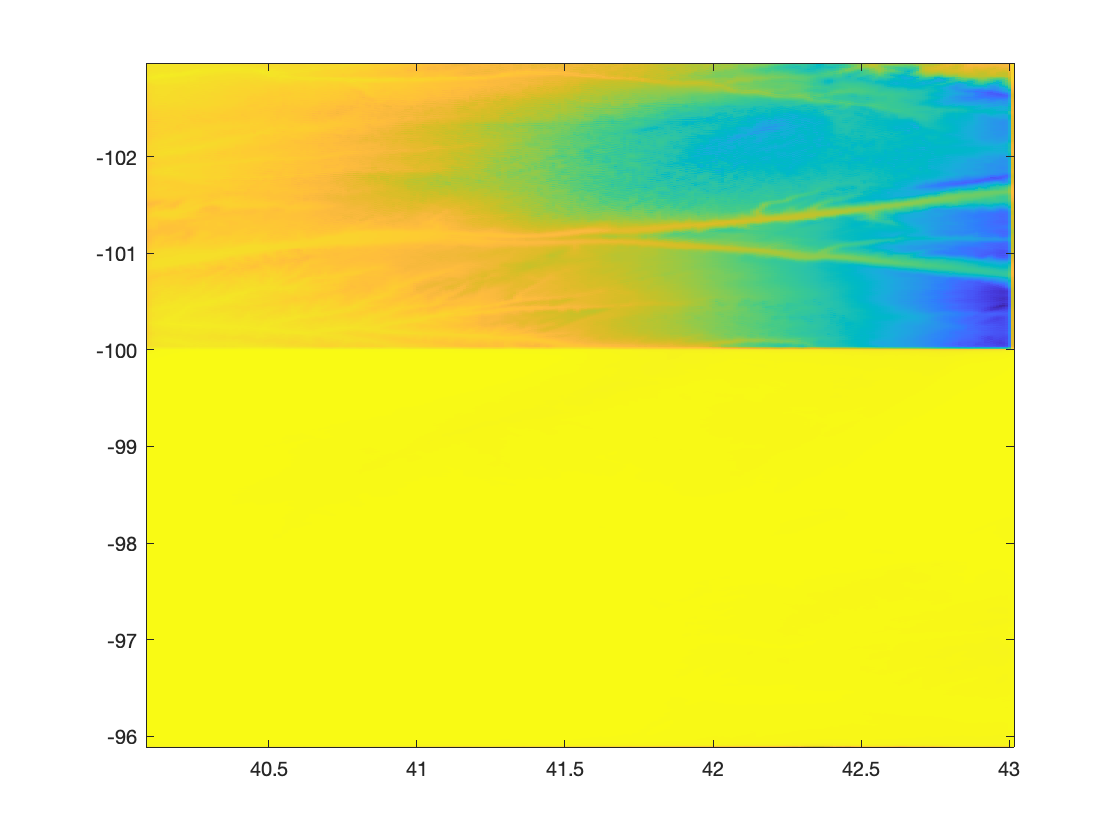

 imagesc(lat,long,deltaN_indirect)

help combine_DEM_data  

  combine_DEM_data(files,Latitude_grid,Longitude_grid) will take input DEM files
  downloaded from SRTM website and user interested Latitue and Longitude grid 
  and give final DEM height matrix mapped over Latitude and Longitude grid.
  input : 
  1 - files - array of strings - each string containg file path of DEM file 
  2 - Latitude grid (double) - Grid of latitudes of area of interest(degrees)
  3 - Longitude grid (double)- Grid of latitudes of area of interest(degrees)
  IMP - Latitude and longitude grid must have minimum resololution of 0.01
  and they must be inside or equal to the area covered by the DEM heights data.
 
  TIP - download DEM values from  here
  
  OUTPUT - 
  H - dem heights mapped over latitude and longitude grid



help im


function H1 = addPadding(H)
    sizeH = size(H);
  
    H1 = [H,zeros([sizeH(1) sizeH(2)-1]);zeros([sizeH(1)-1 sizeH(2)]),zeros([sizeH(1)-1 sizeH(2)-1])];
  %   H1 =  [zeroH,zeroH,zeroH;zeroH,H,zeroH;zeroH,zeroH,zeroH];
end
function H1 = addPadding_full(H)
    sizeH = size(H);
    zeroH = zeros(sizeH);
  %  H1 = [H,zeros([sizeH(1) sizeH(2)-1]);zeros([sizeH(1)-1 sizeH(2)]),zeros([sizeH(1)-1 sizeH(2)-1])];
     H1 =  [zeroH,zeroH,zeroH;zeroH,H,zeroH;zeroH,zeroH,zeroH];
end


%------------------------------------------------------
function gammas = gammas(latitude)
    a = 6378137.0;
    b = 6356752.314140;
    gamma_a = 9.7803267714;
    gamma_b = 9.8321863685;
    omega = 7292115.0*10^11;
    GM = 3986004.418*10^8 ;
    m = ((omega^2)*(a^2)*b)/GM;
    f = (a-b)/a;
    gammas = (a*gamma_a*(cosd(latitude).^2) + b*gamma_b*(sind(latitude).^2))./((a*(cosd(latitude).^2)+b*(sind(latitude).^2)).^0.5);
end